# Trajectory planning for Quadrotor Using Linear Model Predictive Control 

This script defines a continuous-time nonlinear quadrotor model and generates a state function and its Jacobian function as a linearization for the state space reprezentation. It is compact overview how the whole process looks like. 

This work was highly inspired by [https://sal.aalto.fi/publications/pdf-files/eluu11_public.pdf](https://sal.aalto.fi/publications/pdf-files/eluu11_public.pdf)

Pre-start configuration

close all
clear all
set(0,'defaulttextinterpreter','latex')
set(0,'DefaultAxesFontSize',1)

% Determine where your m-file's folder is.
folder = 'src'; 

% Add that folder plus all subfolders to the path.
addpath(genpath(folder));
clear folder

Add path to the solver

cd(fileparts(matlab.desktop.editor.getActiveFilename))
if isunix
    addpath('/home/prochazo/Documents/MATLAB/osqp-matlab');
elseif ispc
    addpath 'C:\Users\mropr\Documents\git\qpOASES\interfaces\matlab'
end

Choose program input/output variables

use_wamv_trajectory = true; % to 
data_file_name = 'usv_states.mat';
% data_file_name = 'usv_states_big_waves.mat';
TrajStart = 185; %245 defines begin of the referenced trajecotry which is loaded from real simulation dataset
% TrajStart = 410; % 375
z_offset = 0;
if z_offset > 0
    fprintf("The reference for z was applied: %i\n",z_offset)
end

Ts = 0.1;     %Sampling time 0.05
fprintf("Sampling time: %f\n", Ts);

Sampling time: 0.100000


N = 15; % Prediction horizon 36
fprintf("Size of the prediction horizon is: %i\n", N);

Size of the prediction horizon is: 15



% Q = diag([3000 3000 40000 10000 10000 3000 1 1 1 100 100 50]); % tracking weight matrix
Q = diag([30 30 40 1 1 50 1 1 5000 1 1 50]); % tracking weight matrix
% P = diag([30 30 40 1 1 30 1 1 1 1 1 50]); % tracking weight matrix
P = diag([0 0 0 0 0 0 0 0 0 0 0 0]); % tracking weight matrix
R = 0.1*eye(4); % input increment weight matrix

setup usage of the constraints

use_soft_constraints = false;
use_slew_rate = true;

M = diag([1 1 1 1 1 1 1 1 1 1 1 1 0 0 0 0]);              % weight on slack variables
L = ones(1,16*N);       % missdesign of the slack variables 


### Create symbolix variables for states, manipulated variables and parameters

syms xt(t) yt(t) zt(t) phit(t) thetat(t) psit(t) xdott(t) ydott(t)...
    zdott(t) phidott(t) thetadott(t) psidott(t) 
syms u1 u2 u3 u4 Ixx Iyy Izz k l m b g
syms x y z phi theta psi xdot ydot zdot phidot thetadot psidot

The twelve states for the quadrotor are:

$[x,y,z,\phi,\theta,\psi,\dot{x},\dot{y},\dot{z},\dot{\phi},\dot{\theta},\dot{\psi}]$,

where

- $\left\lbrack x,y,z\right\rbrack$denote the positions in the inertial frame

- Angle positions $[\phi,\theta,\psi]$ are in the order of roll, pitch, and yaw

- The remaining states are the velocities of the positions and angles

and the others are

- ui: squared angular velocity of rotor *i*

- g: gravitation acceleration

- b: drag constant - propeller constant used for torque

- k: lift constant

- l: distance between rotor and center of gravity

- Iii: diagonal elements of inertia matrix

Group symbolic variables

statet = {
    xt(t) yt(t) zt(t) phit(t) thetat(t) psit(t) xdott(t) ...
    ydott(t) zdott(t) phidott(t) thetadott(t) psidott(t)};
state = {
    x y z phi theta psi xdot ydot zdot phidot thetadot psidot};
    state_diff = {diff(xt(t),t), diff(yt(t),t), diff(zt(t),t), ...
    diff(phit(t),t), diff(thetat(t),t), diff(psit(t),t)};
state_dot = {
    xdot ydot zdot phidot thetadot psidot};
control = [
    u1, u2, u3, u4];

### Set values for dynamics parameters

The difinition of the values was taken from *mrs_simulation/models . *

gVal = 9.81; % gravitation acceleration
% mass = 4.903; % real-drone weight
mass = 3.5; % drone's weight in simulation
d = 0.325; % arm's length
lVal = d*cos(deg2rad(45));
kVal = 24.5; 
bVal = 0.7;

% test values
% kVal = 15.46;
% bVal = 0.1;
% kVal = 23;
% bVal = 0.016;
% bVal = 0.8;

inertia_body_radius = 0.25; 
inertia_body_height = 0.15; %0.05;
rotor_mass = 0; % 0.005 % kg zatim tuto hmotnost zanedbam
motor_mass = 0.148; % kg
propeller_mass = 0.0202;

IxxVal = 2*((rotor_mass+motor_mass+propeller_mass)*lVal^2) + (mass - (rotor_mass+motor_mass+propeller_mass)) * (3 * inertia_body_radius * inertia_body_radius + inertia_body_height * inertia_body_height) / 12; 
IyyVal = 2*((rotor_mass+motor_mass+propeller_mass)*lVal^2) + (mass - (rotor_mass+motor_mass+propeller_mass)) * (3 * inertia_body_radius * inertia_body_radius + inertia_body_height * inertia_body_height) / 12;
IzzVal = 4*((rotor_mass+motor_mass+propeller_mass)*lVal^2) + (mass - (rotor_mass+motor_mass+propeller_mass)) * inertia_body_radius * inertia_body_radius / 2;

% TODO: add weight of the motors like is aproximated in Dynamic Modelling
% of a Quadrotor Aerial Vehicle with Nonlinear Inputs -good paper = DONE

paramValues = [IxxVal IyyVal IzzVal kVal lVal mass bVal gVal];

% working point for linearization
u_work = 0.48*[1 1 1 1]; % minimum rotation^2 of the rotors to be in hover 
state_work = zeros(1,numel(state));

### Transformation matrix for angular velocities from inertial frame to body frame

W = [1, 0, -sin(thetat);
    0, cos(phit), cos(thetat)*sin(phit);
    0, -sin(phit), cos(thetat)*cos(phit)];

### R-ZYX Euler

Rz = [cos(psit), -sin(psit), 0;
    sin(psit), cos(psit), 0;
    0, 0, 1];
Ry = [cos(thetat), 0, sin(thetat);
    0, 1, 0;
    -sin(thetat), 0, cos(thetat)];
Rx = [1, 0, 0;
    0, cos(phit), -sin(phit);
    0, sin(phit), cos(phit)];

Rotation matrix from body frame to inertial frame

Rzyx = Rz*Ry*Rx;

Jacobian (relates body frame to inertial frame velocities)

I = [Ixx, 0, 0; 0, Iyy, 0; 0, 0, Izz];
J = W.'*I*W;

Coriolis forces

dJ_dt = diff(J);
dJ_dt = subs(dJ_dt,[state_diff statet],[state_dot state]);
h_dot_J = [phidott(t), thetadott(t), psidott(t)]*J;
h_dot_J = subs(h_dot_J,[state_diff statet],[state_dot state]);
grad_temp_h = jacobian(h_dot_J,[phi theta psi]);
C = dJ_dt - 1/2*grad_temp_h;

Total thrust

T = k*(u1+u2+u3+u4);

Torques in the direction of phi, theta, psi

tau_beta = [l*k*(- u1 - u2 + u3 + u4); l*k*(- u1 - u4 + u2 + u3); b*(- u1 + u2 - u3 + u4)];

### UAV's dynamics

f(1) = xdott;
f(2) = ydott;
f(3) = zdott;
f(4) = phidott;
f(5) = thetadott;
f(6) = psidott;

Equations for COM configuration

f(7:9) = -g*[0;0;1] + Rzyx*[0;0;T]/m;

Euler Lagrange equations for angular dynamics

f(10:12) = inv(J)*(tau_beta - C*[phidott(t); thetadott(t); psidott(t)]);

Replace parameters and drop time dependence

f = subs(f, [Ixx Iyy Izz k l m b g], paramValues);
f = subs(f,statet,state);
f = simplify(f);

### **Calculate linearization from the UAV's nonlinear model**

Ac = jacobian(f,[state{:}]);
Ac = subs(Ac, state,state_work);
Ac = double(subs(Ac, control,u_work));

Bc = jacobian(f,control);
Bc = subs(Bc, state,state_work);
Bc = double(subs(Bc, control,u_work));

Cc = diag(ones(1,12));
% Cc(7,7) = sqrt(3)/2;
% Cc(7,8) = 1/2;
% Cc(8,7) = 1/2;
% Cc(8,8) = sqrt(3)/2;
    
Dc = zeros(12,4);

sys=ss(Ac,Bc,Cc,Dc);

### Discretize the model of the UAV

model = c2d(sys,Ts);

% Extract the matrices of the discrete state-space description
A = model.A;
B = model.B;
C = model.C;

n = size(A,1); % number of states
m = size(B,2); % number of inputs
p = size(C,1); % number of outputs

## LMPC

The control inputs for the quadrotor are the squared angular velocities of the four rotors:

$[\omega_1^2,\omega_2^2,\omega_3^2,\omega_4^2]$. 

These control inputs create force, torque, and thrust in the direction of the body $z$-axis. In this example, every state is measurable, and the control inputs are constrained to be within [-0.5,0.5] ${\left(\frac{\textrm{rad}}{s}\right)}^2$. Because it was linearized around $\omega^2$ = 0.55, which is the rotation speed when the copter is hovering.

umax = (1-0.35)*[1 1 1 1]';
umin = -0.35*[1 1 1 1]';

### Augment model

Atilde = [A B;
          zeros(m,n) eye(m)];
Btilde = [B;
          eye(m)];
Ctilde = [C zeros(p,m)];

### Calculate sequential form 

%% second part of the equations 
[r, c] = size(Btilde);
ps = zeros(r*N,c);
for i=1:N
    ps(1+(i-1)*r:i*r,:) = Atilde^(i-1)*Btilde;
end
[~, c] = size(ps);

% C double bar
Cdbar = zeros(N*r,N*c);
for i = 0:(N-1)
    Cdbar(:,1+c*i:m+c*i) = [zeros(i*r,m);ps(1:end-i*r,:)];
end
[r, c] = size(Atilde);

% A double hat
Adhat = zeros(r*N,c);
for i = 1:N
    Adhat((i-1)*r+1:(i)*r,:)=Atilde^i;
end

tic;

RCell = repmat({R}, 1, N);
TCell = repmat({Q*Ctilde}, 1, N-1);
QCell = repmat({Ctilde'*Q*Ctilde}, 1, N-1);

Rdbar = blkdiag(RCell{:});
Qdbar = blkdiag(QCell{:},Ctilde'*P*Ctilde);
Tdbar = blkdiag(TCell{:},P*Ctilde);

### Compute H and F matrices

H = Cdbar.' * Qdbar * Cdbar + Rdbar;
F = [(Adhat.' * Qdbar * Cdbar); -Tdbar * Cdbar];

toc

Elapsed time is 0.022165 seconds.


display(toc)

    0.0312



The experimental code which only uses states that are choosen follows ...

% idx = 1;
% for y=0:N-1
%     for z=[1,2,3,13,14,15,16]
%         Cdbar_tmp(idx,:) = Cdbar(y*(n+m)+z,:);
%         Adhat_tmp(idx,:) = Adhat(y*(n+m)+z,:);
%         idx = idx+1;
%     end
% end
% RCell = repmat({R}, 1, N);
% TCell = repmat({eye(3)*eye(3)}, 1, N-1);
% QCell = repmat({eye(3)'*eye(3)*eye(3)}, 1, N-1);
% 
% Rdbar = blkdiag(RCell{:});
% Qdbar = blkdiag(QCell{:},eye(3)'*eye(3)*eye(3));
% Tdbar = blkdiag(TCell{:},eye(3)*eye(3));
% 
% H = Cdbar_tmp.' * Qdbar * Cdbar_tmp + Rdbar;
% F = [(Adhat_tmp.' * Qdbar * Cdbar_tmp); -Tdbar * Cdbar_tmp];

### Calculate constraints

This computation is only to constrain the inputs but is not used since we need to add constraint also on states like are the angles.

To prepare the matrixes we derived this form from following equation, for the maximum $G\Delta u  <= x_{max} - S[x(t), u(t)]^T$ and for the minimum $-G\Delta u  <= -x_{min} + S[x(t), u(t)]^T$. To limit the inputs we limit the input states, which are part of the system since we aougmented the states space representation matrices.

The matrix $G$ is in bottom triangual shape ....

#### Hard constraints

G_out_max = [Cdbar];
S_out_max = [-Adhat];

% W_out_max = repmat([Inf, Inf, Inf, deg2rad(45) deg2rad(45) Inf 2.5882 2.5882 5 5 5 5 umax']',N,1); % 
W_out_max = repmat([Inf, Inf, Inf, deg2rad(45) deg2rad(45) Inf 2 2 4 5 5 5 umax']',N,1); % 
% W_out_min = repmat(-[-Inf, -Inf, -Inf, -deg2rad(45) -deg2rad(45) -Inf -2.5882 -2.5882 -5 -5 -5 -5 umin']',N,1); % 
W_out_min = repmat(-[-Inf, -Inf, -Inf, -deg2rad(45) -deg2rad(45) -Inf -2 -2 -4 -5 -5 -5 umin']',N,1); % 

G_out = [G_out_max;-G_out_max];    
W_out = [W_out_max; W_out_min];
S_out = [S_out_max;-S_out_max];

#### Soft constraints

The clasic hard constrain is $G\Delta \;u<=x_{\max } -S\left\lbrack x\left(t\right),u\left(t\right){\left.\right\rbrack }^T \right.$but for the soft constraints we need to add another slack variable directly into the objective function and also change the constraints in a following way. 


$$\left\lbrack G,-I\right\rbrack \cdot {\left\lbrack \Delta \;u,m\right\rbrack }^T <=W-S\left\lbrack x\left(t\right),u\left(t\right){\left.\right\rbrack }^T \right.$$
 

It is also necessary to limit the size of the slack variable, therefore the 


$$\left\lbrack \begin{array}{cc}
G & -I\\
-G & -I\\
0 & I\\
0 & -I
\end{array}\right\rbrack \cdot {\left\lbrack \Delta \;u,m\right\rbrack }^T <=\left\lbrack \begin{array}{c}
W_{\max } \\
W_{\min } \\
W_{s_{\max } } \\
W_{s_{\min } } 
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
S\\
-S\\
0\\
0
\end{array}\right\rbrack {\left\lbrack \begin{array}{cc}
x\left(t\right) & u\left(t\right)
\end{array}\right\rbrack }^T$$


G_out_soft = [
    Cdbar  -eye(size(Cdbar,1));
   -Cdbar   -eye(size(Cdbar,1));
    zeros(size(Cdbar,1),N*size(Btilde,2))      eye(size(Cdbar,1));
    zeros(size(Cdbar,1),N*size(Btilde,2))      -eye(size(Cdbar,1))
    ];

W_out_soft = [
    W_out_max;
    W_out_min;
    0.2*ones(1,size(Btilde,1)*N)';
    zeros(1,size(Btilde,1)*N)'
    ];

S_out_soft = [
    -Adhat;
    Adhat;
    zeros(size(Btilde,1),size(Btilde,1)*N)';
    zeros(size(Btilde,1),size(Btilde,1)*N)'
    ];

if use_soft_constraints
    mm = M;
    for i = 1:(N-1)
        M = blkdiag(M,mm);
    end
    H = blkdiag(H,M); 
end

#### Slew rate

It is also possible to limit the input signal. Moreover, in this case by limiting the input values we limit the change of the input, because the system was ugmented and as input is used the change of the input.

ub = 0.1*ones(m*N,1);   % Upper bounds
lb = -0.1*ones(m*N,1);  % Lower bounds

G_in = [eye(N*4);-eye(N*4)];
W_in = [ub;-lb];
S_in = [zeros(N*m*2,n),[-repmat(zeros(m),N,1);repmat(zeros(m),N,1)]];

#### Comlete the matrices and prepare them for the optimisation.


if use_soft_constraints
    G = [G_out_soft];
    W = [W_out_soft];
    S = [S_out_soft];
else
    G = [G_out];
    W = [W_out];
    S = [S_out];
end

if use_slew_rate
    G = [G; G_in];
    W = [W; W_in];
    S = [S; S_in];
end


### short_model

Experimental code which decrease the number of states of the UAV's model

N_states = 12;
% A_short = A(1:N_states,1:N_states);
% B_short = B(1:N_states,:);
% C_short = C(1:N_states,1:N_states);
% 
% n_short = size(A_short,1); % number of states
% m = size(B_short,2); % number of inputs
% p_short = size(C_short,1); % number of outputs
% 
% Q = Q(1:N_states,1:N_states);
% Q = diag([30 30 40 1 1 50 1 1 1 1 1 1]);
% P = P(1:N_states,1:N_states);
% 
% % Augmented model
% Atilde = [A_short B_short;
%           zeros(m,n_short) eye(m)];
% Btilde = [B_short;
%           eye(m)];
% Ctilde = [C_short zeros(p_short,m)];
% 
% %% second part of the equations 
% [r, c] = size(Btilde);
% ps = zeros(r*N,c);
% for i=1:N
%     ps(1+(i-1)*r:i*r,:) = Atilde^(i-1)*Btilde;
% end
% [~, c] = size(ps);
% 
% % C double bar
% Cdbar = zeros(N*r,N*c);
% for i = 0:(N-1)
%     Cdbar(:,1+c*i:m+c*i) = [zeros(i*r,m);ps(1:end-i*r,:)];
% end
% [r, c] = size(Atilde);
% 
% % A double hat
% Adhat = zeros(r*N,c);
% for i = 1:N
%     Adhat((i-1)*r+1:(i)*r,:)=Atilde^i;
% end
% 
% RCell = repmat({R}, 1, N);
% TCell = repmat({Q*Ctilde}, 1, N-1);
% QCell = repmat({Ctilde'*Q*Ctilde}, 1, N-1);
% 
% Rdbar = blkdiag(RCell{:});
% Qdbar = blkdiag(QCell{:},Ctilde'*P*Ctilde);
% Tdbar = blkdiag(TCell{:},P*Ctilde);
% 
% H = Cdbar.' * Qdbar * Cdbar + Rdbar;
% F = [(Adhat.' * Qdbar * Cdbar); -Tdbar * Cdbar];

## Simulation

### Generate the reference signal

if use_wamv_trajectory == true
    [Duration, ref] = WamvReferenceTrajectory(N, Ts, TrajStart, data_file_name);
    t = 0:Ts:Duration; % time vector
else
    Duration = 20; % Final time
    t = 0:Ts:Duration; % time vector
    ref = referenceTrajectory([t, Duration+Ts:Ts:Duration+(N*Ts)])';
end

### Intial conditions

x0 = zeros(n,1); 
% x0(1) = ref(1,1);
% x0(2) = ref(1,2);
% x0(3) = ref(1,3);
x0(1) = ref(1,1);
x0(2) = ref(1,2);
x0(3) = 8;

u0 = zeros(m,1); 
xtilde0 = [x0; u0];
touchdownMoment = 0

touchdownMoment = 0

simEnd = inf;

Initialize the matrices where the simulation results will be stored

x = zeros(n, numel(t));
y = zeros(p, numel(t));
u = zeros(m, numel(t));

x(:,1) = x0;
y(:,1) = C*x0;
uprev = u0;

### Initialize OSQP (uncomment if OSQP is used)

mosqp = osqp;
settings = mosqp.default_settings();
settings.verbose = 0;
settings.eps_abs = 1e-05;
settings.eps_rel = 1e-05;
settings.polish = 1;
settings.check_termination = 10;
settings.max_iter = 4000;
% settings.warm_start = 1;
% settings.time_limit = 0.018;
if use_soft_constraints
    mosqp.setup(sparse(H/2+H'/2), [[x(1:N_states,i)' uprev' vec(ref(1:N, 1:N_states)')']*F, L], sparse(G), -inf*ones(size(W)), W+S*[x(:,i); uprev], settings);
else
    mosqp.setup(sparse(H/2+H'/2), [x(1:N_states,i)' uprev' vec(ref(1:N, 1:N_states)')']*F, sparse(G), -inf*ones(size(W)), W+S*[x(:,i); uprev], settings);
end

%% in case of qpOASES
% myOptions = qpOASES_options;
% myOptions.maxIter = 1000;
% myOptions.maxCpuTime = 0.1;

### Simulation for-cycle

% hbar = waitbar(0,'Simulation Progress');
for i = 1:(numel(t)-1)
    tic;
    % Reference signal over the current prediction window
    rk_raw = ref(i:i+N-1, 1:N_states)';
    
    rk = preprocessReference(rk_raw, x(:,i), Ts);
    
    % Recompute H and F based on change of penalization matrix Q, which is
    % changed based on UAV's state and position
        vert_dist = abs(x(3,i) - rk_raw(3,1));
        Q(3,3) = 40 + 10000/exp(20*vert_dist);   % z 
        Q(4,4) = 1 + 50000/exp(10*vert_dist);     % roll
        Q(5,5) = 1 + 50000/exp(10*vert_dist);     % pitch
        Q(9,9) = 3000 + 3000/exp(25*vert_dist);     % z velocity
%         Q(10,10) = 1 + 1000/exp(10*vert_dist);
%         Q(11,11) = 1 + 1000/exp(10*vert_dist);
        TCell = repmat({Q*Ctilde}, 1, N-1);
        QCell = repmat({Ctilde'*Q*Ctilde}, 1, N-1);
        Rdbar = blkdiag(RCell{:});
        Qdbar = blkdiag(QCell{:},Ctilde'*P*Ctilde);
        Tdbar = blkdiag(TCell{:},P*Ctilde);
        H = Cdbar.' * Qdbar * Cdbar + Rdbar;
        F = [(Adhat.' * Qdbar * Cdbar); -Tdbar * Cdbar];  
    
    % Solve the QP
    % by quadprog from Optimization Toolbox ...
%     qp_res = quadprog(H/2+H'/2, [x(:,i)' uprev' rk(:)']*F, G, W+S*[x(:,i); uprev], [], [], [], [], [], optimoptions('quadprog', 'Display', 'off'));
%     qp_res = quadprog(H/2+H'/2, [x(:,i)' uprev' rk(:)']*F, G, W+S*[x(:,i); uprev], [], [], lb, ub, [], optimoptions('quadprog', 'Display', 'off'));
  
    % or by qpOASES ...
%     [qp_res,fval,exitflag,iter,lambda,auxOutput] = qpOASES(H/2+H'/2, F'*[x(:,i)' uprev' rk(:)']', G, [], [], [], W+S*[x(:,i); uprev]);

    % or by OSQP
    if use_soft_constraints
        H = blkdiag(H,M);
        mosqp.update('Px', nonzeros(triu(sparse(H/2+H'/2))) , 'q', [[x(1:N_states,i)' uprev' rk(:)']*F, L], 'u', W+S*[x(:,i); uprev]);
    else
        mosqp.update('Px', nonzeros(triu(sparse(H/2+H'/2))), 'q', [x(1:N_states,i)' uprev' rk(:)']*F, 'u', W+S*[x(:,i); uprev]);
    end
    results = mosqp.solve();
    qp_res = results.x;
    
    % Extract the incement in u
    duk = qp_res(1:m,1);
    
    u(:,i) = uprev + duk;
    
    % Simulate the system 
    x(:,i+1) = A*x(:,i) + B*u(:,i);
    y(:,i+1) = C*x(:,i+1);
        
    uprev = u(:,i);
%     waitbar(i*Ts/Duration,hbar);
    if touchdownMoment == 0 && checkTouchdown(x(:,i+1), rk_raw) == true
        touchdownMoment = i+1;
    end
    if touchdownMoment ~= 0 && abs(touchdownMoment - i) > 3/Ts % let simulation run for 3 sec after touchdown
        simEnd = i;
        break
    end
    
    time_c(i) = toc;
end
% close(hbar)

Summation of the working point

u = u_work'+u;
ref(:,3) = ref(:,3) - z_offset;

## Plot the results (just for your convenience)

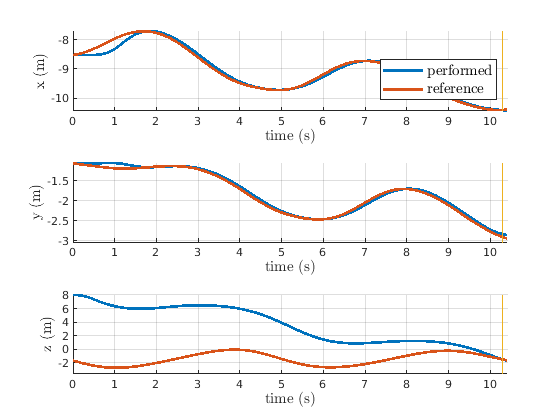

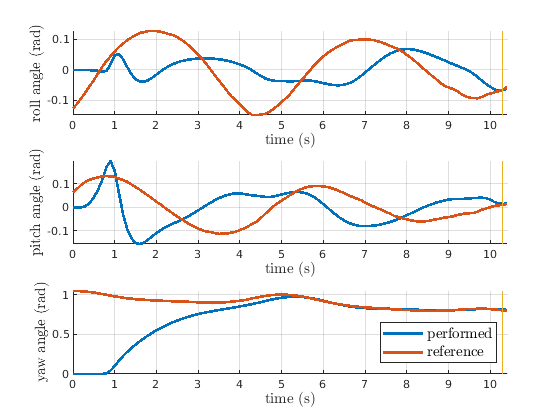

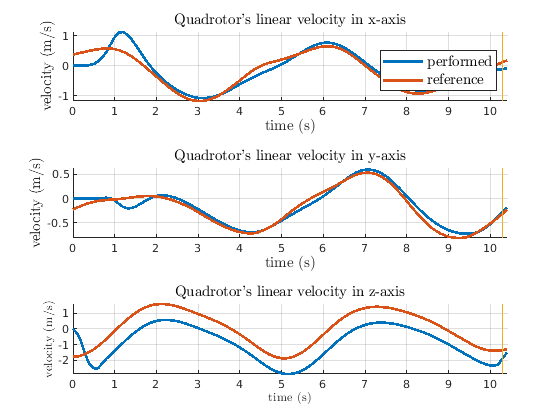

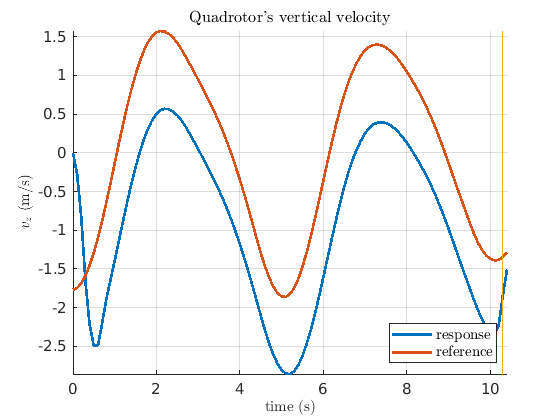

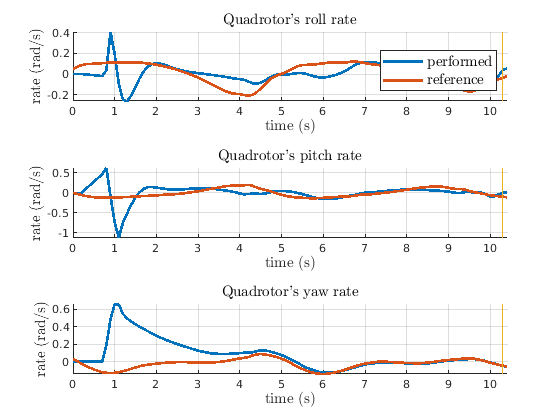

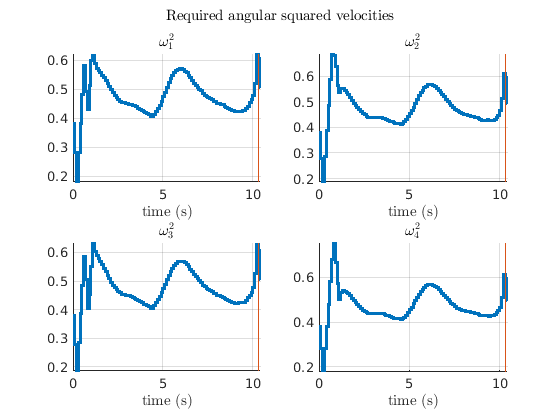

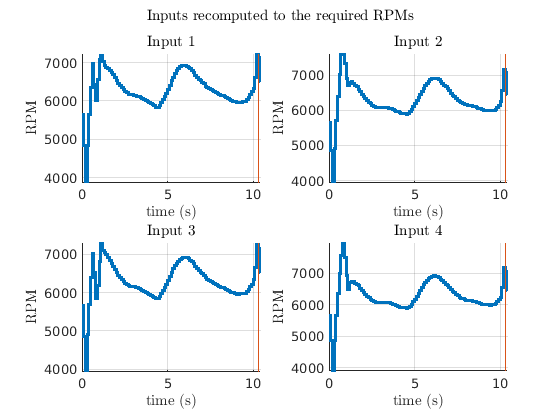

% figure(1)
% x1 = subplot(211);
% stairs(t, ref(1:numel(t),1:3), 'k--');
% hold on
% % stairs(t, ref(1:numel(t),4:6), 'k:');
% stairs(t, y(1:3,:)');
% hold off
% title('Outputs')
% xlabel('Time (s)')
% ylabel('States')
% grid on
% axis tight
% legend('x','y','z', 'x','y','z')
% 
% x2 = subplot(212);
% stairs(t, u');
% title('Controls')
% xlabel('Time (s)')
% ylabel('$\omega (rad/s)^2$')
% grid on
% legend(' \omega_1^2 ',' \omega_2^2 ',' \omega_3^2 ',' \omega_4^2 ')
% 
% linkaxes([x1 x2],'x');
plotResult;

% animate;

% drone_Animation(y(1,:)',y(2,:)',y(3,:)',y(4,:)',y(5,:)',y(6,:)', t, ref)